## Datos generales

g = -9.81; %Gravedad
denAire = 1.2; %Densidad del aire
cDrag = 1.29; %Coeficiente de resistencia
step = 0.5; %Diferencia de tiempo
h = 3768; %Altura del volcán

### Preparación para graficar

clc %Limpia la consola
hold on
title("Proyectiles 3D"); %Pone el título a la gráfica
grid minor %Muestra la cuadrícula
axis equal %Hace que los ejes tengan la misma relación
v = 0; %Inicialización de variable auxiliar que permite la rotación de la pantalla
zlim([0 inf]) %Hace que no se vean números menores a 0
x2d = {}; %Permite que se pueda hacer la gráfica 2d
y2d = {};
dm = 0; %Va a guardar la distancia máxima llegada de algún proyectil en la simulación

### Graficación del volcán

[xv,yv] = meshgrid(-190:10:190); %Crea los valores correspondientes a X y Y
zv = (0.1*(-(xv.^2)-(yv.^2))+h); %Crea el valor de Z del volcán
contour3(xv,yv,zv,400, 'Color', [0.5 0.1 0.1]) %Grafica el contorno del volcán

### Proyectiles

nr = input("Dame el número de rocas: "); %Número de rocas
for i = 1:nr

    %Generación de los datos aleatorios
    vi = randi([55 200]); %Velocidad inicial
    tetha = randi([30 80]); %Ángulo del proyectil
    denRoca = randi([2000 3500]); %Densidad de la roca
    r = randi([250 300])/100; %Radio de la roca
    o = randi([0 360]); %Angulo en z
    areaRoca = pi*power(r,2); %Área de la roca
    volRoca = (4/3)*pi*power(r,3); %Volumen de la roca
    masaRoca = volRoca*denRoca; %volRoca
    b = (1/2)*cDrag*denAire*areaRoca;

    %Creación de los vectores vacíos
    x = [];
    vx = vi*cosd(tetha);
    ax = 0;
    y = [];
    vy = vi*sind(tetha);
    ay = g;
    x(2) = 0;
    y(2) = h;
    x(1) = x(2)-vx*step;
    y(1) = y(2)-vy*step+(1/2)*g*power(step,2);
    ya=y(2);
    xa=x(2);
    aux2dx = "0"; %Variables auxiliares para poder graficar en 2d
    aux2dy = int2str(h);

    %Generación de valores siguientes
    n = 3; %Valor actual de la posición en su respectivo tiempo
    while(ya>0) %Calculos aplicando fórmula de Verlet
        ax = (-b*power(vx, 2))/masaRoca;
        x(n) = (2*x(n-1)-x(n-2))+(1/2)*ax*power(step,2);
        vx = (x(n)-x(n-1))/step;
        ay = -(vy/abs(vy))*((b*power(vy,2))/masaRoca)+g;
        y(n) = ((2*y(n-1)-y(n-2))+(1/2)*ay*power(step,2));
        vy = (y(n)-y(n-1))/step;
        ya = y(n); %Y actual
        xa = x(n); %X actual
        zg = ya; %Variables que se usarán para la graficación
        xg = xa*cosd(o);
        yg = xa*sind(o);
        vzg = vy; %Variable de la velocidad actual
        vxg = vx*cosd(o);
        vyg = vx*sind(o);
        plot3(xg,yg,zg, '-o', 'MarkerSize',1, 'Color', [i/nr*0.3 i/nr 0.5]); %Graficación de trayectorias
        plot3(-xg,-yg,zg)
        quiver3(xg,yg,zg,vxg,vyg,vzg,0, 'Color', [i/nr*0.3 i/nr 0.5]);
        pause(0.01) %Espera de tiempo para pasar a la siguiente iteración
        aux2dx = aux2dx+"|"+xa; %Se pasan los datos a un string ya que se comprimen los datos
        aux2dy = aux2dy+"|"+ya;
        n = n+1;
        view([v 18]) %Permite la rotación de cámara
        v = v+0.3;
    end
    x2d = [x2d, aux2dx];
    y2d = [y2d, aux2dy];
    str = "Proyectil "+i; %Permite marcar que proyectil fue cual al impacto
    text(xg,yg,zg, str)
    distanciaCentro = norm([xg yg]);
    disp("El proyectil "+i+" alcanzó una distancia de "+distanciaCentro+" metros.")

end

El proyectil 1 alcanzó una distancia de 7323.6151 metros.


El proyectil 2 alcanzó una distancia de 3648.9706 metros.


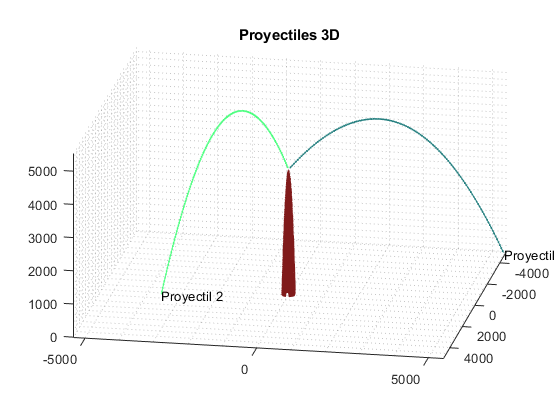

for i=0:50
    view([v 18])
    v = v+0.3;
    pause(0.01)
end
hold off

### Graficación 2D

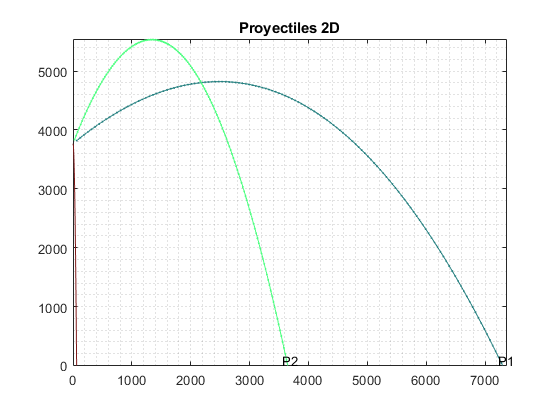

xv = linspace(0,190); %Datos del contorno del volcán
yv = -xv.^2+h;
plot(xv,yv,'Color', [0.5 0.1 0.1]) %Grafica el contorno del volcán
hold on
title("Proyectiles 2D"); %Pone el título a la gráfica
grid minor %Muestra la cuadrícula
axis equal %Hace que los ejes tengan la misma relación
ylim([0 inf])
xlim([0 inf])
for i = 1:nr
    xs=split(x2d(i),["|"]); %Descomprime los datos de la gráfica 2d
    ys=split(y2d(i),["|"]);
    xs=str2double(xs); %Convierte a float los strings
    ys=str2double(ys);
    for j = 2:length(xs)
        plot(xs(j),ys(j), '-o', 'MarkerSize',1, 'Color', [i/nr*0.3 i/nr 0.5]); %Graficación de trayectorias
        quiver(xs(j),ys(j),xs(j)-xs(j-1),ys(j)-ys(j-1),0,'Color', [i/nr*0.3 i/nr 0.5]); %Graficación de trayectorias
        pause(0.01)
    end
    str = "P"+i; %Permite marcar que proyectil fue cual al impacto
    text(xs(end)-100,100, str)
    dm = max([xs(end) dm]); %Actualiza el valor en dado caso de que sea la distancia más larga
end

disp("En esta simulación, la distancia más larga alcanzada por un proyectil fue de "+dm+" metros.") %Marca la distancia más larga

En esta simulación, la distancia más larga alcanzada por un proyectil fue de 7323.6151 metros.
